clear all; close all;
load('Entire_region.mat')

top25max_all_year = nan(51, 20);

RGB = [254,229,217
252,187,161
252,146,114
251,106,74
239,59,44
203,24,29
153,0,13];

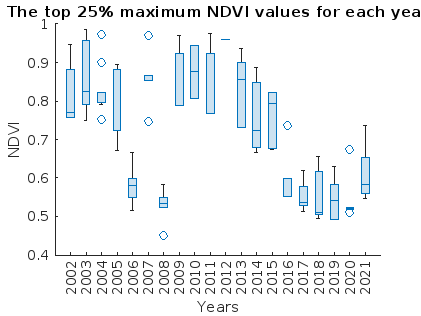

count_A = [];
for i = 3:22
    max_NDVI = max(T{:,i});
    min_NDVI = min(T{:,i});
    
    A = T{:,i} >= max_NDVI - (max_NDVI - min_NDVI)./4;
    
    xi = T{:,i}(A)';
    top25max_all_year(1:length(xi),i-2) = xi;
    A = double(A);
    count_A = [count_A A];
end
clear i; clear max_NDVI; clear min_NDVI; clear A;
clear xi; 
boxchart(top25max_all_year)
set(gca,'XTickLabel',{'2002','2003','2004','2005', ...
    '2006','2007','2008','2009','2010','2011','2012','2013', ...
    '2014','2015','2016','2017', '2018','2019','2020','2021'});
ylabel('NDVI'); xlabel('Years');
title('The top 25% maximum NDVI values for each year');
saveas(gcf,'Published_Plots\Figure_8.a.pdf')

count_A = sum(count_A, 2);
T.freq_top25 = count_A;


A = ~isnan(ndvi(:,:, 15));
Z_count_A = [];
x = 0;
for i = 1:nc
    z_count_A_col = [];

    indx = find(A(:,i)>0);

    start_indx = indx(1);
    end_indx = indx(end);

    z_count_A_col(1:start_indx-1) = NaN;

    z_count_A_col(indx) = count_A(x+1: x+length(indx));

    z_count_A_col(end_indx+1:nr) = missing;

    x = x+length(indx);
    Z_count_A = [Z_count_A z_count_A_col'];
end
clear A; clear end_indx; clear start_indx; clear i; 
clear x; clear z_count_A_col;  clear indx


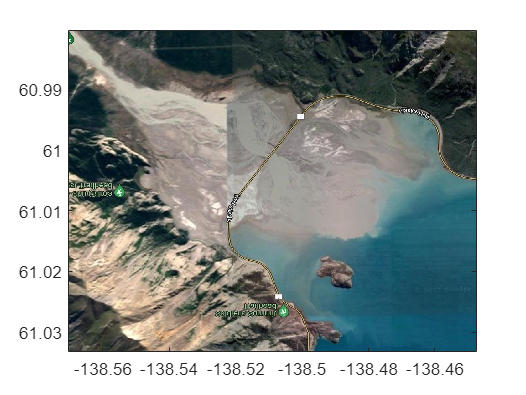

img=imread('Yukon_delta.jpg'); 
image([ -138.447718 -138.570218],[61.033109 60.980258], img);
hold('on');

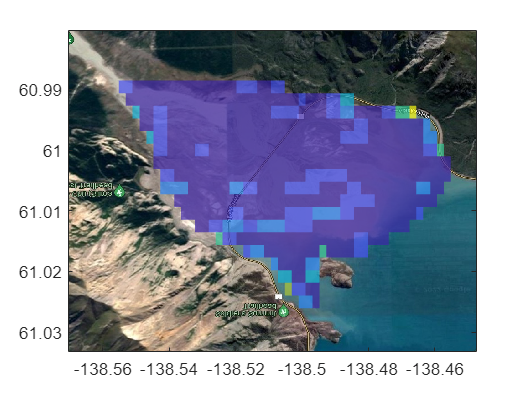

[nr,nc]=size(Z_count_A);
s= pcolor([X(:,1);nan],[Y(1,:), nan],[Z_count_A nan(nr,1); nan(1,nc+1)]' );
s.EdgeColor = 'none' ;
s.FaceAlpha = 0.7;

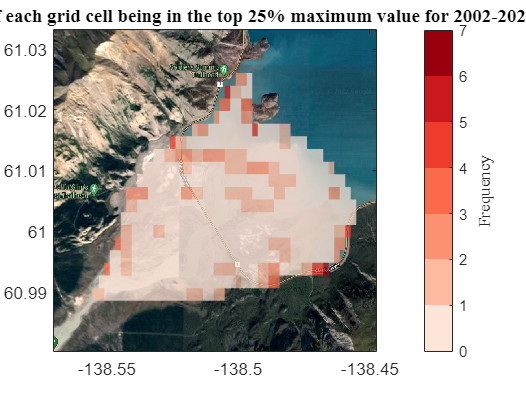


c = colorbar; 
c.Label.String = 'Frequency';
c.Label.FontName = 'Dialog';
c.Label.FontSize = 10;
colormap(RGB./255);


%xlabel("Longitude"); ylabel("Latitude"); 
title("Frequency of each grid cell being in the top 25% maximum value for 2002-2021",'FontName', 'Dialog')

set(gca, 'xDir', 'reverse') 
set(gca,'XAxisLocation','top','YAxisLocation','right','ydir','reverse');
camroll(180)
hold off;
saveas(gcf,'Published_Plots\Figure_8.b.pdf')

clear c; clear s; clear img;